# Undistort a diffracted image

As a simple use case I undistort an diffracted image. 

The image was taken with a Sony Alpha7c camera. Three lasers (red, green, and blue) at fixed locations were shone towards a camera. The camera lens had a diffraction grating affixed, so the lasers appear diffracted. The image was taken with long exposure (2 seconds) while rotating the lens - hence the circular image.

The 'circles' do not appear as perfect circles due to the distortion introduced by diffraction. We assume that the only distortion present is due to diffraction (wide angle lens distortion is pretty much completely corrected by the camera manufacturer). The goal is to compute a coordinate transformation that would turn the 'circles' into true circles.

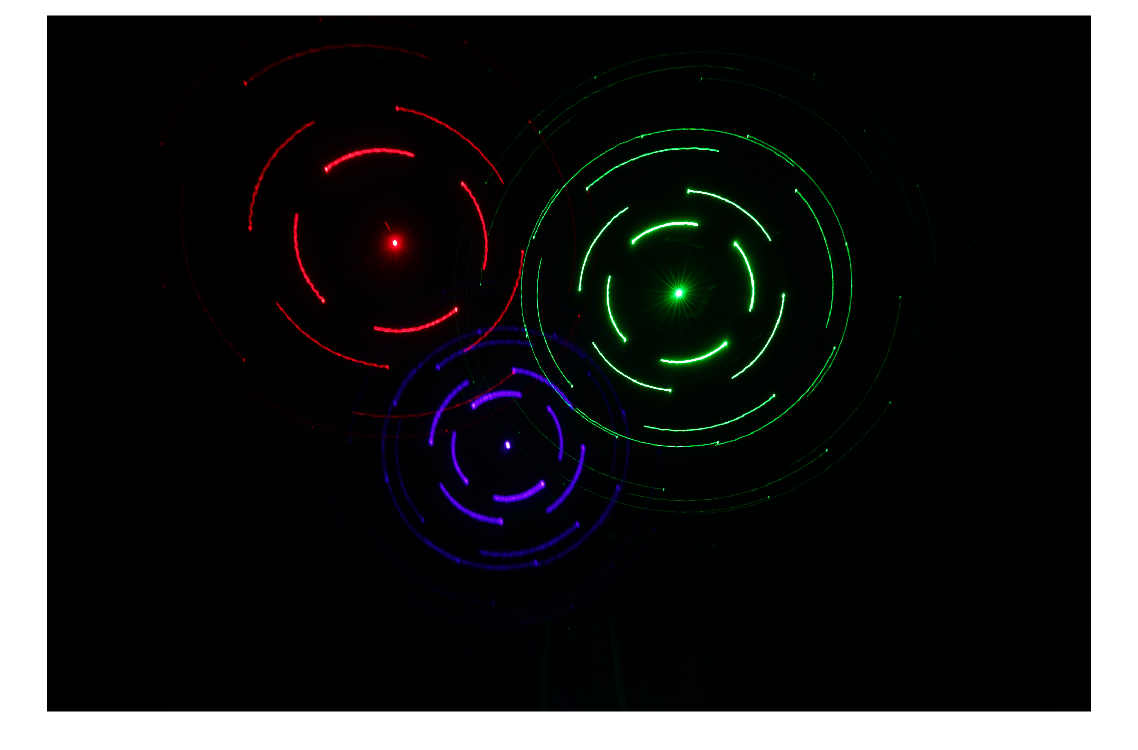

addpath('..')

img_fn = '../images/DSC01556.jpg';
img = imread(img_fn);
imshow(img)

Below are the lens specs.

dims = size(img); 
dims = dims([2, 1]); % image resolution
f = 24; % focal length in mm
sensorsz = [35.8, 23.8]; % sensor dimensions in mm
pix = mean(sensorsz./dims); % sensor pitch in mm (mm per pixel)


The interesting fact is that the distortion introduced by diffraction only depends on 1) focal length, 2) image's pixel resolution, and 3) the physical dimensions of the sensor and nothing else. Below's how the coordinate transform matrices look like. Basically diffraction turns squares into pin-cushions. We will be able to undistort the initial image by applying *inverse* warping using $U$ and $V$.

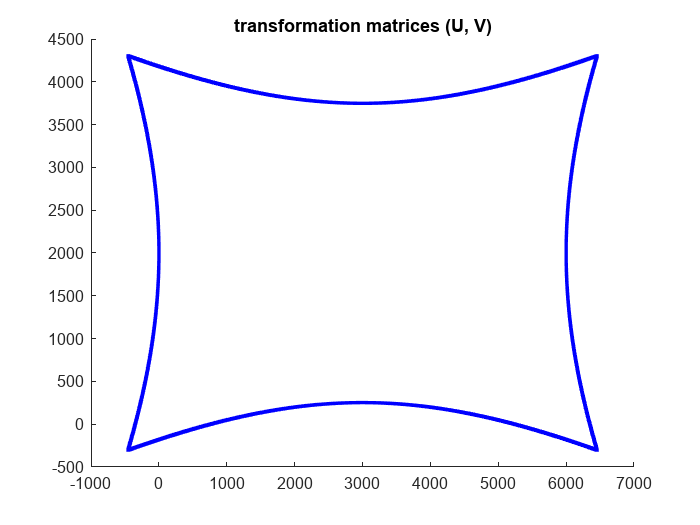

[U, V]=getUV([], dims, pix, f);

figure
hold on
plot(U(1, :), V(1, :), 'b.')
plot(U(end, :), V(end, :), 'b.')
plot(U(:, 1), V(:, 1), 'b.')
plot(U(:, end), V(:, end), 'b.')
hold off
title('transformation matrices (U, V)')

Given the coordinate transformation matrices $U$ and $V$ it is a simple matter to undo the effects of diffraction.

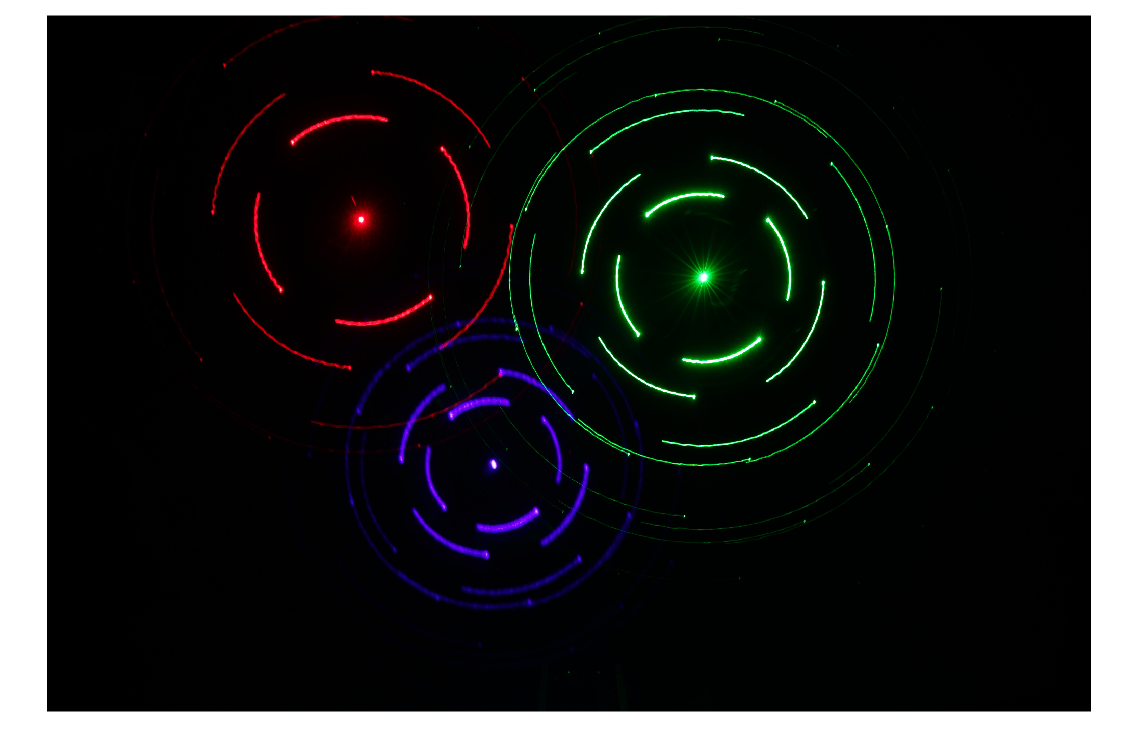

img_undistorted = imtformarray(img, U, V); % wrapper for matlab's tformarray() function
figure
imshow(img_undistorted)

Re-distorting the undistorted is also straightforward -- it is just a matter of computing the inverse transformations of $U$ and $V$.

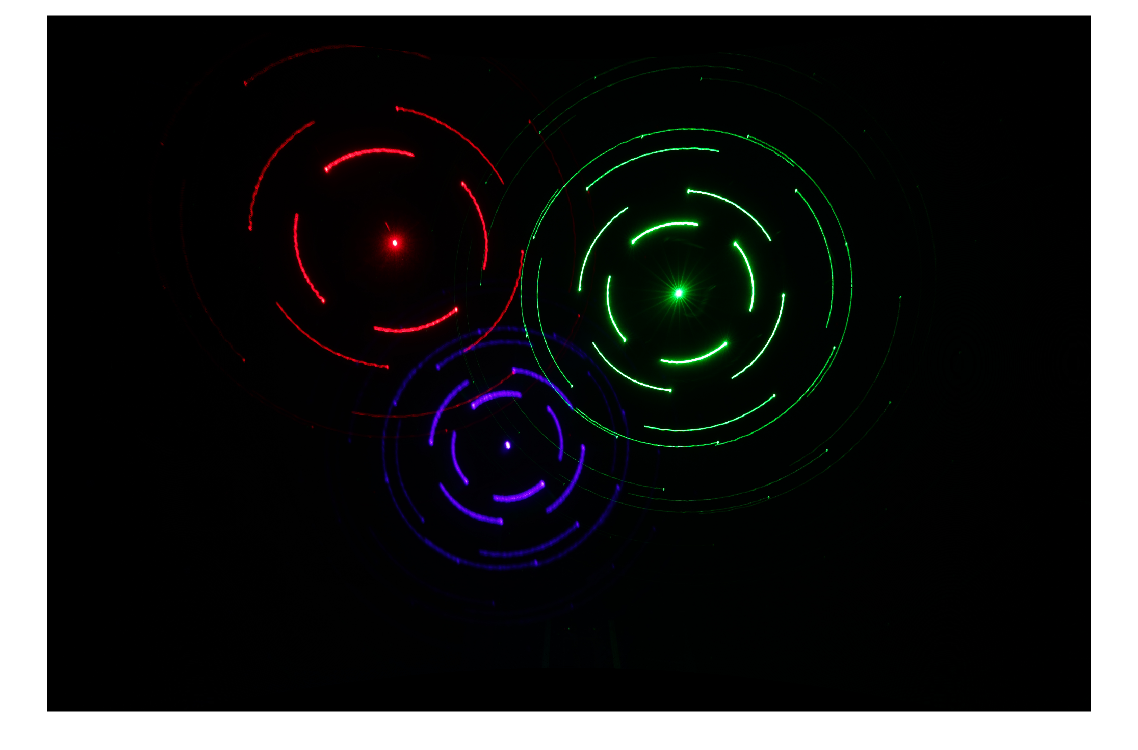

img_redistorted = imtforminv(img_undistorted, U, V);
figure
imshow(img_redistorted)